clear
clc

# HTail Design Calculator V1

#### By James Orendi

## HTail Sizing & Design

#### Input Data

wing_area = 0.5 ; % m^2, Predicted Wing Area of Aircraft, for use in Tail Volume Analysis
MAC_graph_output = 0.2 ; % m, Predicted Wing Mean Aerodynamic Chord Length, for use in Tail Volume Analysis

C_H = 0.5 ; % N/A, Tail Volume Coefficient
S_H_S = 0.175 ; % N/A, Tail to Wing Area Ratio


Htail_dihedral = 0; % deg
AR_H = 5 ; % N/A, Aspect Ratio of Tail
Htail_TR =0.3 ; % N/A, Horizontal Tail Taper Ratio

sweep_type = 3 ;
Htail_sweep = 0 ; % deg, Horizontal Tail Sweepback

#### Function Call

addpath([cd,'/Functions'])
[Htail_area,~] = Tail_Volume_Analysis(wing_area,C_H,S_H_S,MAC_graph_output) ;
[x_Htail_data,y_Htail_data,H_span,H_c_r,H_c_t,Htail_opp,Htail_sweep,~,Htail_opp_2,Htail_adj_2,Htail_xlim,Htail_ylim] = Planform_Calc_1taper(Htail_area,AR_H,Htail_TR,Htail_dihedral,Htail_sweep,sweep_type) ;

#### Htail Planform Plot

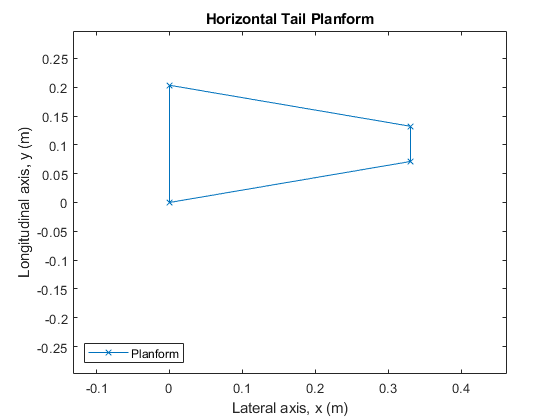

figure
plot(x_Htail_data,y_Htail_data,'x-')
xlim([Htail_xlim(1),Htail_xlim(2)]) % Graphical Display View limits, x axis
ylim([-Htail_ylim,Htail_ylim]) % Graphical Display View limits, y axis
legend("Planform","Location","Southwest")
title("Horizontal Tail Planform")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")

#### MAC Graphical Calculation Function Call

[y_mac_Htail_data_1,y_mac_Htail_data_2,y_mac_Htail_data_3,y_mac_Htail_data_4,x_mac_Htail_data_1,x_mac_Htail_data_2,Htail_mac_graph_line_x_points,Htail_mac_graph_line_1_data,Htail_mac_graph_line_2_data,Htail_mac_graph_data_y,Htail_mac_graph_data_x,Htail_graph_AC,Htail_quarter_chord_x,Htail_quarter_chord_y] = Planform_MAC_1taper(H_span,H_c_t,H_c_r,Htail_opp);

### Htail MAC Graphical Plot

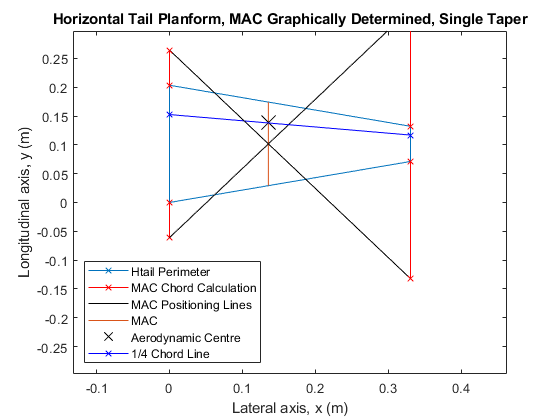

figure
plot(x_Htail_data,y_Htail_data,'x-')
hold on
plot(x_mac_Htail_data_1,y_mac_Htail_data_1,'x-','Color','r')
plot(Htail_mac_graph_line_x_points,Htail_mac_graph_line_1_data,'-','Color','k')
plot(Htail_mac_graph_data_x,Htail_mac_graph_data_y,'-','Color',[0.8500 0.3250 0.0980])
plot(Htail_graph_AC(1),Htail_graph_AC(2),'x', 'Color','k','MarkerSize',15)
plot(Htail_quarter_chord_x,Htail_quarter_chord_y,'x-', 'Color','b')
plot(Htail_mac_graph_line_x_points,Htail_mac_graph_line_2_data,'-','Color','k')
plot(x_mac_Htail_data_1,y_mac_Htail_data_2,'x-','Color','r')
plot(x_mac_Htail_data_2,y_mac_Htail_data_3,'x-','Color','r')
plot(x_mac_Htail_data_2,y_mac_Htail_data_4,'x-','Color','r')
xlim([Htail_xlim(1),Htail_xlim(2)]) % Graphical Display View limits, x axis
ylim([-Htail_ylim,Htail_ylim]) % Graphical Display View limits, y axis
legend("Htail Perimeter","MAC Chord Calculation","MAC Positioning Lines","MAC","Aerodynamic Centre","1/4 Chord Line","Location","Southwest")
title("Horizontal Tail Planform, MAC Graphically Determined, Single Taper")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off

### Full Htail Planform Plot

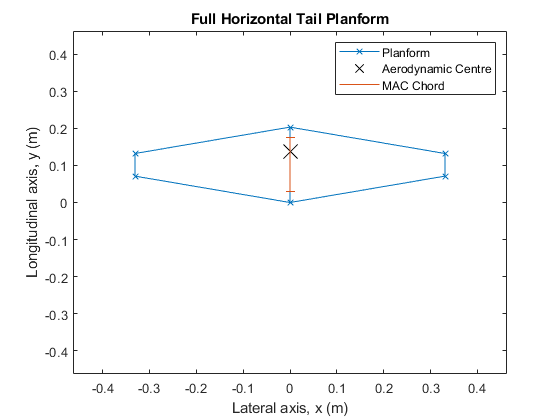

figure
plot(x_Htail_data,y_Htail_data,'x-',"Color",[0 0.4470 0.7410])
hold on
plot(0,Htail_graph_AC(2),'x', 'color','k','MarkerSize',15)
plot(-x_Htail_data,y_Htail_data,'x-',"Color",[0 0.4470 0.7410])
plot([0 0],Htail_mac_graph_data_y,'_-','Color',[0.8500 0.3250 0.0980])
title("Full Horizontal Tail Planform")
legend("Planform","Aerodynamic Centre","","MAC Chord")
xlim([-Htail_xlim(2),Htail_xlim(2)]) % Graphical Display View limits, x axis
ylim([-Htail_xlim(2),Htail_xlim(2)]) % Graphical Display View limits, y axis
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off

## Htail Control Surface Sizing

### Input Data

elevator_area_ratio_desired = 30/100 ; % N/A, Ratio of Control Surface Area to Horizontal Tail Area

CS_type = 1 ;

% SPANWISE PIVOT
Htail_span_ratio = 0.8 ; % N/A, Ratio of Control Surface Span to Horizontal Tail Span, for Spanwise Pivot ONLY

% CONSTANT CHORD
elevator_chord_ratio = 0.5 ; % N/A, Ratio of Control Surface Chord to Horizontal Tail Chord, for Constant Chord ONLY

#### Function Call

if CS_type == 1
    [Htail_x_control_surface_data,Htail_y_control_surface_data] = CS_Spanwise_Pivot(elevator_area_ratio_desired,Htail_span_ratio,Htail_opp_2,Htail_adj_2,H_span,H_c_r,H_c_t,Htail_opp,Htail_sweep) ;
elseif CS_type == 2
    [Htail_x_control_surface_data,Htail_y_control_surface_data,Htail_S_control_ratio] = CS_Constant_Chord(elevator_area_ratio_desired,Htail_opp_2,Htail_adj_2,H_span,Htail_sweep,elevator_chord_ratio,H_c_r,H_c_t,Htail_opp) ;
end

### Full Horizontal Tail Control Surface Planform Plot

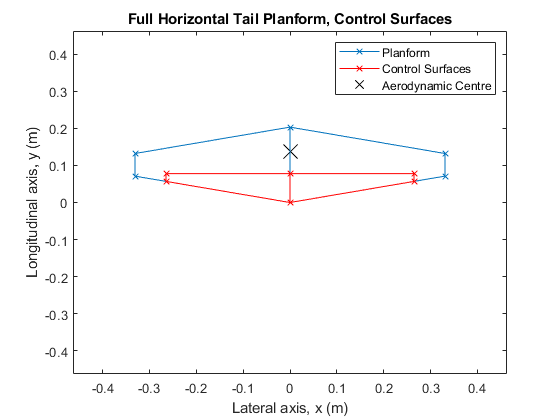

figure
plot(x_Htail_data,y_Htail_data,'x-',"Color",[0 0.4470 0.7410])
hold on
plot(Htail_x_control_surface_data,Htail_y_control_surface_data,'x-',"Color",'r')
plot(0,Htail_graph_AC(2),'x', 'color','k','MarkerSize',15)
plot(-x_Htail_data,y_Htail_data,'x-',"Color",[0 0.4470 0.7410])
plot(-Htail_x_control_surface_data,Htail_y_control_surface_data,'x-',"Color",'r')

title("Full Horizontal Tail Planform, Control Surfaces")
legend("Planform","Control Surfaces","Aerodynamic Centre")
xlim([-Htail_xlim(2),Htail_xlim(2)]) % Graphical Display View limits, x axis
ylim([-Htail_xlim(2),Htail_xlim(2)]) % Graphical Display View limits, y axis
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off